%----------------------------------------------------------------------------
% Descripción: Prpgrama para realizar la segmentación de imágenes térmicas
% y extraer la información de lo valores de temeperatura
% Autores: Mario Balcazar, Rocío Soto
%----------------------------------------------------------------------------

clear; clc; close all;
cd 'D:\Chio Soto\PUCP\2021-2\Trabajo de tesis 2\SDK\dji_thermal_sdk_v1.0_20201110\utility\bin\windows\release_x64';

%% Entrada: carpeta en donde se encuentran las imágenes a procesar y creación
% de archivos .raw de donde se extrae la información de temperatura
dos('dji_irp_omp.exe -s ../../../../dataset/H20T/ -a measure -o measure_p');

DIRP API version number : 0x10 
DIRP API magic version  : 212f812 
R-JPEG source file directory : ../../../../dataset/H20T/ 
FILE [0] ../../../../dataset/H20T/\DJI_20220129180621_0004_T.JPG 
FILE [1] ../../../../dataset/H20T/\DJI_20220129180631_0005_T.JPG 
FILE [2] ../../../../dataset/H20T/\DJI_20220129180703_0006_T.JPG 
FILE [3] ../../../../dataset/H20T/\DJI_20220129180732_0007_T.JPG 
Process R-JPEG file : ../../../../dataset/H20T/\DJI_20220129180621_0004_T.JPG 
Process R-JPEG file : ../../../../dataset/H20T/\DJI_20220129180631_0005_T.JPG 
Process R-JPEG file : ../../../../dataset/H20T/\DJI_20220129180703_0006_T.JPG 
Process R-JPEG file : ../../../../dataset/H20T/\DJI_20220129180732_0007_T.JPG 
R-JPEG version information 
    R-JPEG version : 0x1 
    header version : 0x103 
 curve LUT version : 0x1 
R-JPEG resolution size 
      image  width : 640 
      image height : 512 
Run action 1 
R-JPEG version information 
    R-JPEG version : 0x1 
    header version : 0x103 
 curve LUT vers

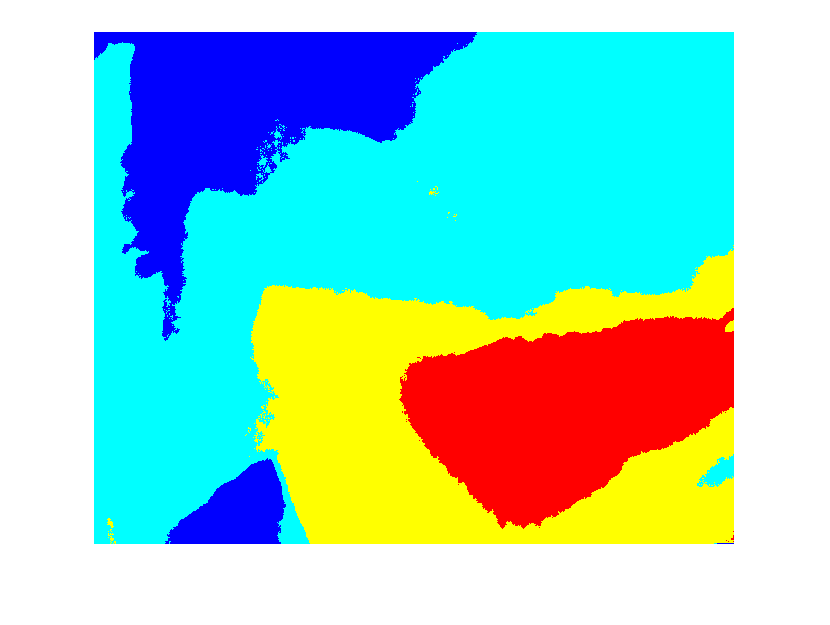

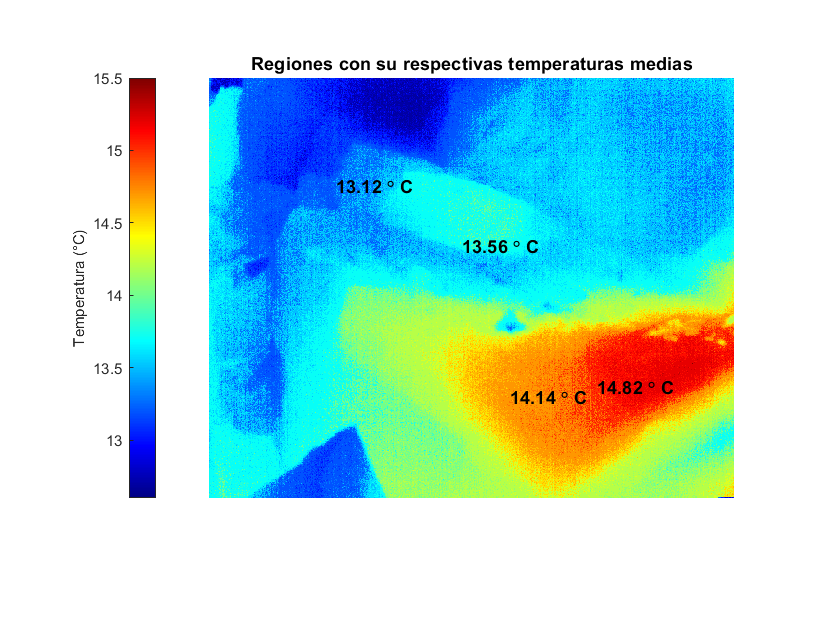

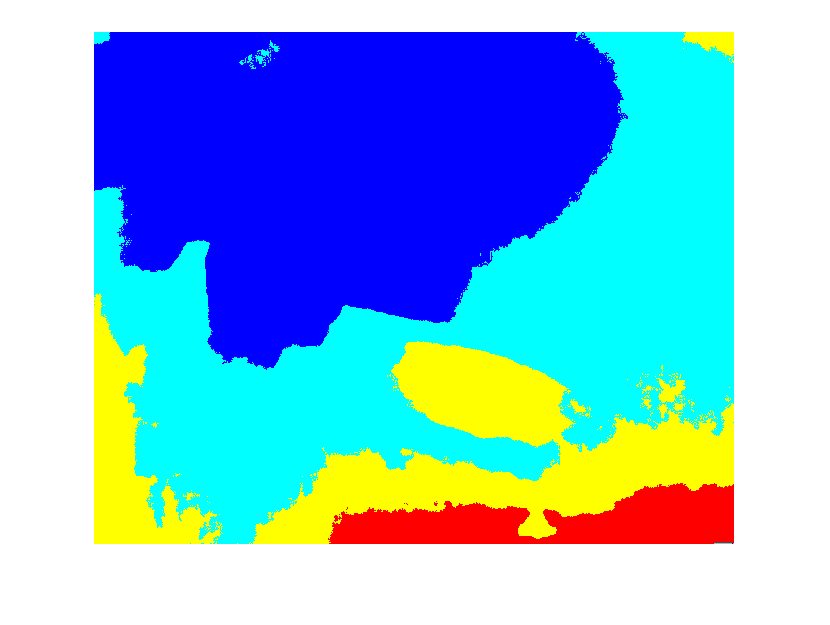

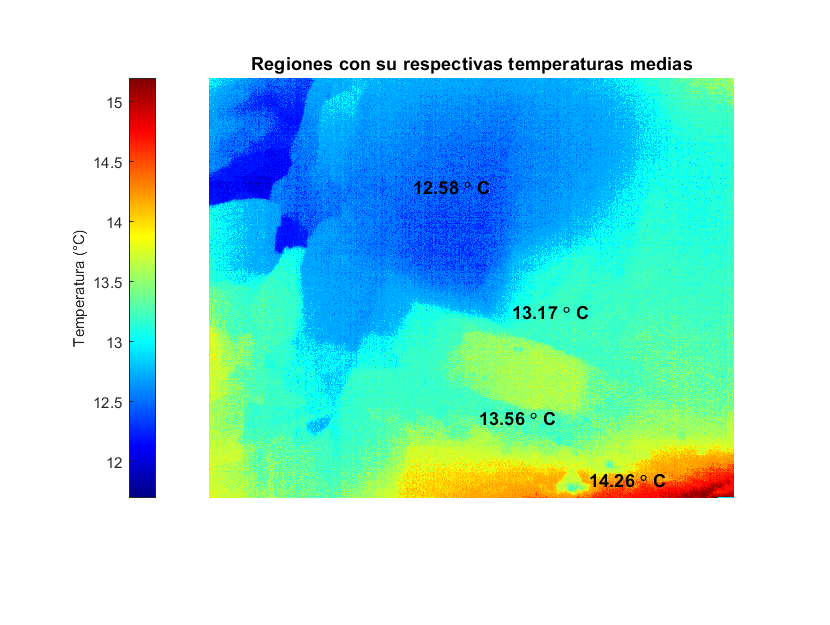

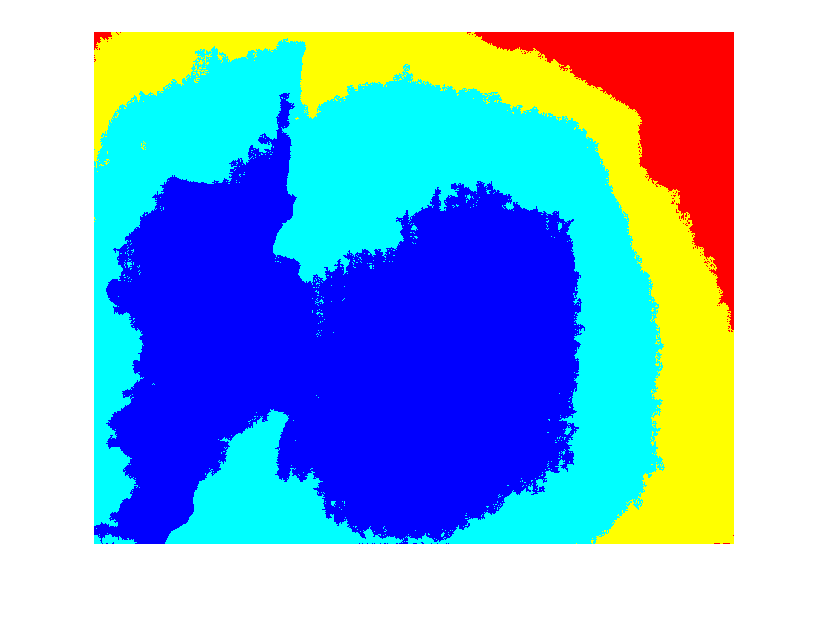

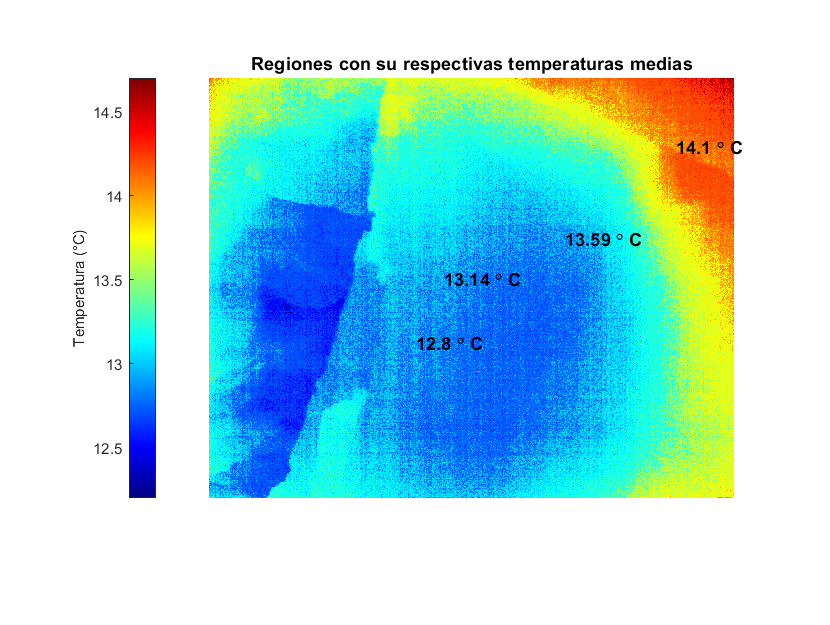

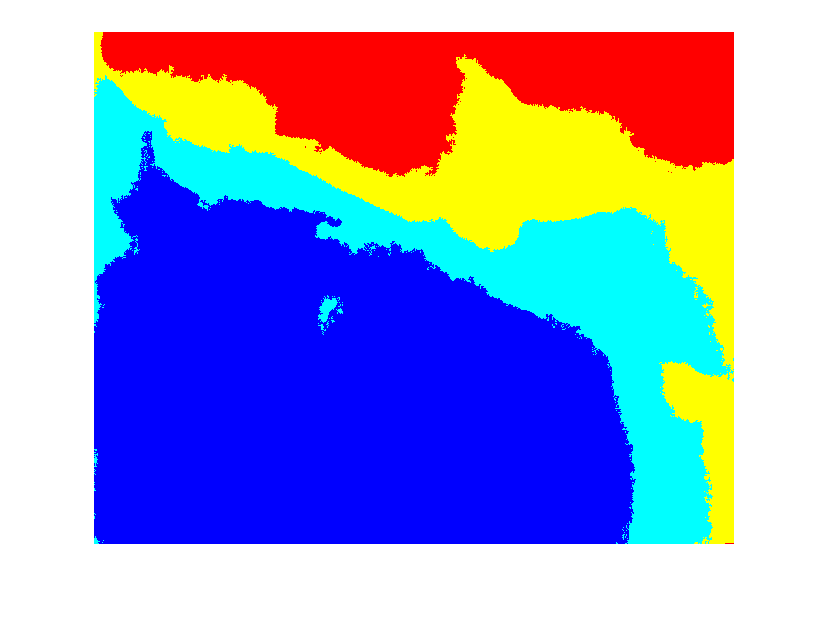

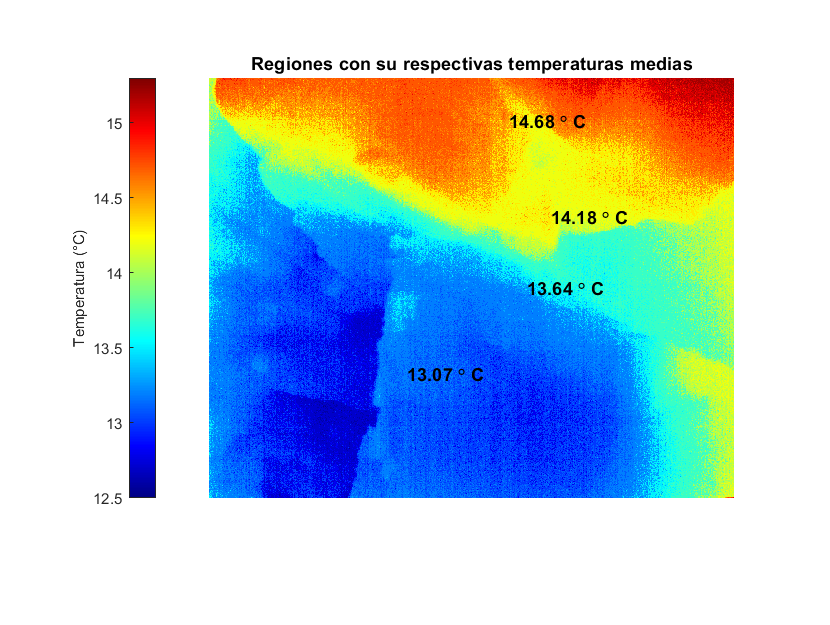


% Creación de carpetas donde se guardarán las imágenes procesadas
mkdir 'D:\Chio Soto\INCIMMET\Pruebas 24-01-2022\labor3-p1\Después' SegmentedImg
mkdir 'D:\Chio Soto\INCIMMET\Pruebas 24-01-2022\labor3-p1\Después' LabeledImg

% Definición del ancho y alto de la imagen
width = 640; height = 512;

%% Bucle de procesamiento y visualización de las imágenes térmicas
i = 0;
while (1)
	% Apertura y escalamiento de la imagen que se desea procesar
	filename = "measure_p_"+i+".raw";
	fileID = fopen(filename,'r');
	if (fileID == -1)
		break;
	end
	img = fread(fileID,width*height,'int16',0,'l');
	fclose(fileID);
	min_img = min(img)/10; max_img = max(img)/10;
	img = reshape(img, [width,height]); img = img/10; img = img';
	
	% Rango dinámico de los dtos de temperatura en °C
	range = [min(img(:)) max(img(:))];
	
	% Suavizado de la imagen para eliminar el ruido
	smoothValue = 0.01*diff(range).^2;
	J = imguidedfilter(img,'DegreeOfSmoothing',smoothValue);
	
	% Umbrales que se utilizan en la segmentación
	thresh = multithresh(J,3);
	
	% Segmentación de la imagen y relleno de los agujeros
	L = imquantize(J,thresh); L =imfill(L); 
	figure(); imshow(label2rgb(L));
	
    % Almacenamiento de imagen segmentada en carpeta específica
    name = "Segmented_Img" + i + ".png";
    name = char(name);
    carp = 'D:\Chio Soto\INCIMMET\Pruebas 24-01-2022\labor3-p1\Después\SegmentedImg';
    name = [carp,'\',name];
    hgsave(name);
    imwrite(label2rgb(L),name) 
	
	% Extracción de las propiedades de la imagen para etiquetar las
	% temperaturas promedio
	props = regionprops(L,img,{'MeanIntensity','Centroid'});
	figure(); imshow(img,[]);
	colormap(gca,"jet"); c = colorbar('westoutside');
	c.Label.String = 'Temperatura (°C)';
	title('Regiones con su respectivas temperaturas medias');
	
	for n = 1:numel(props)
		% Texto que muestra la temperatura promedio en °C
		T = [num2str(props(n).MeanIntensity,4) ' \circ C'];
		text(props(n).Centroid(1),props(n).Centroid(2),T,'Color','k','FontSize',11,'FontWeight',"bold");
    end
      
    % Almacenamiento de imagen con datos en carpeta específica
    name = "Labeled_Img" + i + ".jpg";
    name = char(name);
    carp = 'D:\Chio Soto\INCIMMET\Pruebas 24-01-2022\labor3-p1\Después\LabeledImg';
    name = [carp,'\',name];
    hgsave(name);
    saveas(gcf,name)
    i = i+1;
end